,Get operating point

% run trimming.m file
run('linear_analysis/trimming.m')

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(8.87548e-04) main_to_linearize/Drone Dynamics/Actuator Dynamics/by_actuator_resp
(1.11022e-15) main_to_linearize/Drone Dynamics/Actuator Dynamics/motor_resp_top/State Space
(1.11022e-15) 

Linearize model from rate input to rate output

mdl = 'main_to_linearize'

mdl = 'main_to_linearize'

io(1) = linio('main_to_linearize/att_control/pitch_rate', 1, 'input')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y


io(2) = linio('main_to_linearize/Drone Dynamics/w_b_comp', 2, 'output')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y



G_rate = linearize(mdl, io, op)


G_rate =
 
  A = 
                    p,q,r (1)     p,q,r (2)  bx_actuator_  bx_actuator_  by_actuator_  by_actuator_  Transport De  Transport De  Transport De  Transport De
   p,q,r (1)                0     -2.41e-37        -239.6     1.958e+04             0             0    -6.581e+04             0             0             0
   p,q,r (2)         2.41e-37             0             0             0        -239.6     1.958e+04             0             0    -6.581e+04             0
   bx_actuator_             0             0        -13.13        -72.64             0             0             0             0             0             0
   bx_actuator_             0             0             1             0             0             0             0             0             0             0
   by_actuator_             0             0             0             0        -13.13        -72.64             0             0             0             0
   by_actuator_             0             0  

bode(G_rate)
step(G_rate)
nyquist(G_rate)
% [num, den] = ss2tf(G_rate.A, G_rate.B, G_rate.C, G_rate.D)
% s = tf('s')
% G_rate_tf = tf(num, den) * exp(-0.2*s)
% [A,B,C,D] = tf2ss(G_rate_tf.Numerator{1}, G_rate_tf.Denominator{1})
% G_rate = ss(A,B,C,D) 

Control System Designer

controlSystemDesigner(G_rate)

Disk Margin Check

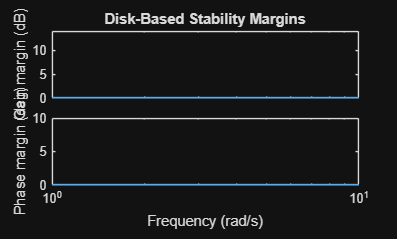

s = tf('s');
format long g;
C = (0.056819 * (21*s + 1)) / s;

diskmarginplot(C*G_rate)

diskmargin(C*G_rate)

ans = struct with fields:
           GainMargin: [1 1]
          PhaseMargin: [0 0]
           DiskMargin: 0
           LowerBound: 0
           UpperBound: 0
            Frequency: NaN
    WorstPerturbation: [1×1 ss]



G_cl = minreal(feedback(C * G_rate, 1))

5 states removed.

G_cl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1      -16.39    0.004576      0.7469      -25.14      -44.83      -68.95
   x2    1.28e-07    -0.02559      -8.176         281      -36.27     0.04063
   x3    2.39e-05      -5.947       -1919   6.804e+04       -8814       9.775
   x4  -0.0007248     -0.2468       -71.7        2378        4297       9.349
   x5   -0.003569     0.00388      0.2606       11.21        -576     -0.8524
   x6       1.832     0.02326       5.158      -133.8       -1362      0.5571
 
  B = 
       pitch_rate
   x1   -0.008866
   x2  -2.617e-09
   x3  -8.545e-07
   x4   3.037e-05
   x5  -6.102e-06
   x6    0.000417
 
  C = 
               x1          x2          x3          x4          x5          x6
   y1   4.826e-10      0.2223      -1.194     -0.0338   -0.001196  -1.278e-07
 
  D = 
       pitch_rate
   y1           0
 
Continuous-time state-space model.


bw_rad = bandwidth(G_cl)

bw_rad =           5.82962167480305
